# Offset Free Tracking and Unmeasured Disturbance Rejection-Part2 

## Introduction

In the [previous lesson](matlab:open('./L04_OffsetFreeControl.mlx')), we have seen that the state feedback control law generates an offset if 

- The unmeasured disturbances influencing state dynamics are non-stationary, i.e. they have slowly drifting behavior 

- Mismatch exists between the plant and the model. 

To achieve offset free control in the presence of disturbances, we use [estimation techniques](matlab:open('./L03_KalmanFilter.mlx')). In this lesson we will see how we compensate for the offset resulting in the controlled output due to these disturbances using "Innovation Bias" technique.

## Realistic State Feedback Control 

If it is desired to move the system from the equilibrium point to an arbitrary setpoint, then the state feedback control law $u\left(k\right)=-G\hat{x\;} \left(k\right)$ has to be further modified.

**Game Plan: **

- To begin with, we assume very simple disturbance model: constant, additive and known disturbances in the state dynamics and in the measured outputs

- The state feedback control law is modified to reject these disturbances and deal with an arbitrary but constant setpoint. 

- We then further modify the controller to deal with time varying disturbances and setpoints 

- Select a suitable model for unmeasured disturbance compensation and implement the state feedback controller 

### Artificial Unknown Disturbance Model

Consider the problem of designing a state feedback controller for a general system governed by difference equation


$$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_{\beta } \beta_s \\
y\left(k\right)=\textrm{Cx}\left(k\right)+C_{\eta } \eta_s 
\end{array}$$


such that it is controlled at an arbitrarily specified setpoint **r**


$$y\left(k\right)=r,k\to \infty$$


Further, assume that

- Input disturbance signal $\beta_s$ and the associated matrix $\Gamma_{\beta }$ and

- Additive output disturbance signal $\eta_s$ and the associated matrix $C_{\eta }$

are known apriori and system is asymptotically stable.

## State & Disturbance Estimation: Slow Varying Disturbances

The assumption that the disturbance model and disturbance signals are known apriori is highly restrictive. In practice, most disturbances affecting system dynamics are not measured or known. Thus, we need to find ways of capturing the effects of unmeasured disturbances on system dynamics. In this study we focus on two different approaches. 

- **Innovation Bias Approach**: Use the **innovation signal** **e(k)** generated by **disturbance free model based state estimator** as a proxy for disturbance signals

- **State Augmentation Approach**: Modify the state space model by including additional states that can capture effects of unmeasured disturbances and redesign observer   

When the true states evolve as follows 


$$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_{\beta } \beta \left(k\right)\\
y\left(k\right)=\textrm{Cx}\left(k\right)
\end{array}$$


and states are estimated using a disturbance free model based observer 


$$\begin{array}{l}
\hat{x\;} \left(k+1\right)=\Phi \hat{x\;} \left(k\right)+\Gamma u\left(k\right)+\textrm{Le}\left(k\right)\\
e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)
\end{array}$$


then it can be argued that the innovation signal contains information on state and output disturbances  


$$e\left(k\right)=\textrm{Cx}\left(k\right)+C_{\eta } \eta \left(k\right)-C\hat{x\;} \left(k\right)$$


thus, we can use **e**(k) **as a proxy **for the disturbance signal

 
$$y\left(k\right)=\textrm{Cx}\left(k\right)+C_{\eta } \eta \left(k\right)$$


Compare the assumed **system dynamics **with **disturbance free model based observer **

**System Dynamics: **


$$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_{\beta } \beta \left(k\right)\\
y\left(k\right)=\textrm{Cx}\left(k\right)+C_{\eta } \eta \left(k\right)
\end{array}$$


**Disturbance Free Model Based Observer **


$$\begin{array}{l}
\hat{x\;} \left(k+1\right)=\Phi \hat{x\;} \left(k\right)+\Gamma u\left(k\right)+\textrm{Le}\left(k\right)\\
e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)
\end{array}$$


 If use **e**(k) **as a proxy **for the disturbance signal, then  from the above two sets of equations, 


$$\beta \left(k\right)=e\left(k\right)\;\textrm{and}\;\Gamma_{\beta } =L$$



$$\eta \left(k\right)=e\left(k\right)\;\;\;\textrm{and}\;C_{\eta } =I$$


### Innovation Bias Approach 

Thus, by innovation bias method, we use the innovations from the state estimator e(k) as a measure of MPM 


$$\hat{\beta} \left(k\right)=e\left(k\right)\;\textrm{and}\;\Gamma_{\beta } =L$$



$$\hat{\eta} \left(k\right)=e\left(k\right)\;\;\;\textrm{and}\;C_{\eta } =I$$


With these choices of disturbance signals


$$K_{\beta } =C{\left\lbrack I-\Phi \right\rbrack }^{-1} L$$


The steady state target inputs and states are given as 


$$\begin{array}{l}
u_s \left(k\right)=Ku^{-1} \left\lbrace r\left(k\right)-\left(K_{\beta } -I\right)e\left(k\right)\right\rbrace \\
x_s \left(k\right)={\left\lbrack I-\Phi \right\rbrack }^{-1} \left\lbrace \Gamma_u u_s \left(k\right)+\textrm{Le}\left(k\right)\right\rbrace 
\end{array}$$


Till now we assumed that disturbances are slowly varying with time, i.e. they have low frequency component only. What if, in addition, disturbances are contaminated with high frequency noise?  

## State & Disturbance Estimation: Disturbances with High Frequency Noise

When the true states evolve as follows 


$$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_{\beta } \beta \left(k\right)+w\left(k\right)\\
y\left(k\right)=\textrm{Cx}\left(k\right)+C_{\eta } \eta \left(k\right)+v\left(k\right)
\end{array}$$


where **w**(k) and **v**(k) are random zero mean white noise signal (i.e. high frequency signal), and state is estimated as


$$\begin{array}{l}
\hat{x\;} \left(k+1\right)=\Phi \hat{x\;} \left(k\right)+\Gamma u\left(k\right)+\textrm{Le}\left(k\right)\\
e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)
\end{array}$$
 

then the innovation signal contains **high frequency noise signal  **


$$e\left(k\right)=\textrm{Cx}\left(k\right)+C_{\eta } \eta \left(k\right)+v\left(k\right)-C\hat{x\;} \left(k\right)$$


**Consequence:** The traget origin (xs (k),us (k)) will fluctuate at high frequency. 

**Remedy: **Filter the innovation signal through a unity gain filter to remove high frequency component and retain only the low frequency disturbances influencing the system dynamics.


$$e\left(k\right)=\textrm{Cx}\left(k\right)-C\hat{x\;} \left(k\right)$$



$$e_f \left(k\right)=\Phi_e e\left(k-1\right)+\left(1-\Phi_e \right)e\left(k\right)$$



$$\Phi_e =\alpha I\;\textrm{and}\;0\le \alpha <1$$


**α** is a tuning parameter which is typically chosen between 0.9 to 0.99.

### Unity Gain Filter

Consider a unity gain 1′st order transfer function, used for filtering a signal e(t) to generate ef (t)


$$e_f \left(s\right)=\frac{1}{1+\tau s}e\left(s\right)$$


In discrete time (with sampling interval T), this is equivalent to 


$$e_f \left(z\right)=\frac{1-\alpha }{z-\alpha }e\left(z\right)\;\textrm{where}\;\alpha =e^{\frac{-T}{\tau }}$$


Note: 0<α<1  for any  $\tau <0$ Or in time domain 


$$e_f \left(k+1\right)=\alpha e_f \left(k\right)+\left(1-\alpha \right)e\left(k\right)$$


The filter is often implemented by removing the unit delay, i.e.


$$e_f \left(k\right)=\alpha e_f \left(k-1\right)+\left(1-\alpha \right)e\left(k\right)$$
 

### Controller with Robustness Filter

Thus, the following assumptions are made in the innovation bias formulation regarding the **state** and the **output disturbances** 


$$\hat{\beta} \left(k\right)=e_f \left(k\right)\;\textrm{and}\;\Gamma_{\beta } =L$$



$$\hat{\eta} \left(k\right)=e_f \left(k\right)\;\textrm{and}\;C_{\eta } =I_{r\times r}$$


Further it is assumed that these disturbances remain constant over the future. Thus, **modified state feedback control law** using the filtered innovations as proxy for disturbance is 


$$\begin{array}{l}
u\left(k\right)=u_s \left(k\right)-G\left\lbrack x\left(k\right)-x_s \left(k\right)\right\rbrack \\
u_s \left(k\right)=K_u^{-1} \left\lbrace r\left(k\right)-\left(K_{\beta } +I\right)e_f \left(k\right)\right\rbrace \\
x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \left\lbrace {\Gamma u}_s \left(k\right)+Le_f \left(k\right)\right\rbrace 
\end{array}$$


### Innovation Bias Approach

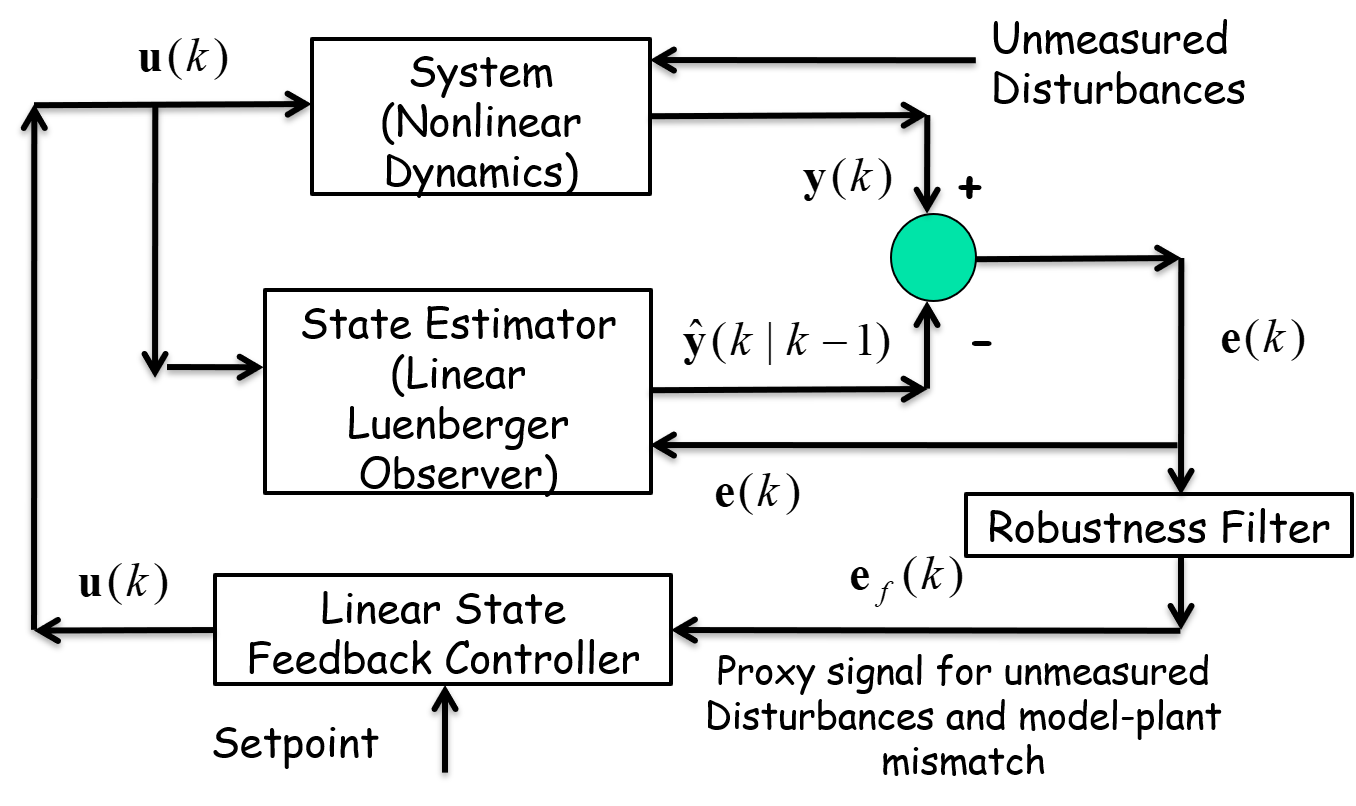

**Innovation Bias Algorithm Summary:**

Sequence of calculation steps at k′th sampling instant"

- Get measurement at instant k:   $y\left(k\right)=Y\left(k\right)-Y_s$

- Compute innovation: $e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)$ 

- Filter innovations:  $e_f \left(k\right)=\Phi_e e\left(k-1\right)+\left(1-\Phi_e \right)e\left(k\right)$

- Compute target input and target state 


$$u_s \left(k\right)=K_u^{-1} \left\lbrace r\left(k\right)-\left(K_{\beta } +I\right)e_f \left(k\right)\right\rbrace$$



$$x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \left\lbrace {\Gamma u}_s \left(k\right)+Le_f \left(k\right)\right\rbrace$$


- Compute Control Law

 
$$u\left(k\right)=u_s \left(k\right)-G\left\lbrack \hat{x} \left(k\right)-x_s \left(k\right)\right\rbrack$$


- Impose input constraints:    $U_L -U_s \le u\left(k\right)\le U_H -U_s$

- Communicate input $U\left(k\right)=u\left(k\right)+U_s$  to system

- Update state estimator:  $\hat{x\;} \left(k+1\right)=\Phi \hat{x\;} \left(k\right)+\Gamma u\left(k\right)+\textrm{Le}\left(k\right)$ 

## Example: Quadruple Tank System: Closed Loop Simulation

close all;
clc             % clear screen 

global QTank  % Define global variables 


Select the operating point 1: **Minimum Phase System, (2) Non-Minimum Phase System**

operating_pt=1;
% Initialization of parameters and simulation conditions 
if ( operating_pt == 1 )                           % Minimum phase system
    load QTank_MinPhase_Model_1 
elseif ( operating_pt == 2 )                    % Non-Minimum phase system 
    load QTank_NonMinPhase_Model_new.mat
end


Specify System Simulation Type: **(1) Linearized model OR (2) Nonlinear model **

plant_sim=1;

Select Sampling time:

samp_T=4;

Select number of samples in the simulation run

Ns=300;

n_st = 4 ;   % No. of states 
n_op =  2 ;   % No. of measured outputs  
n_ip = 2 ;   % No. of man. inputs  
n_d = 1;  % No. of disturbances

% Create matrices for saving simulation results
Xk = zeros(n_st, Ns) ;     % State Profiles             
Uk = zeros(n_ip, Ns) ;     % Input Profiles
Dk = zeros(n_d, Ns) ;     % Disturbance Profile 
Yk = zeros(n_op, Ns) ;    % Output Profile

uk = zeros(n_ip, Ns) ;     % Input Profiles (perturbation)
yk = zeros(n_op, Ns) ;    % Output Profile (perturbation) 

% Develop discrete linear perturbation model
if ( operating_pt == 1 )    
load QTank_Min_ContLinmod  % Load linearized system matrices 
else
    load QTank_NonMin_ContLinmod  % Load linearized system matrices 
end
QTank.phy = expm( A_mat * samp_T ) ;
QTank.gama_u = (QTank.phy - eye(n_st)) * inv( A_mat ) * B_mat ;
QTank.gama_d = (QTank.phy - eye(n_st)) * inv( A_mat ) * H_mat ;

% State Estimator Initialization
xkpred = zeros(n_st, Ns) ; %  Create Dummy matrices for estimated states
ek = zeros(n_op, Ns) ;        % Innovation sequence 
ek(:,1) = yk(:,1) - QTank.C_mat * xkpred(:,1) ;
est_err = zeros(n_st, Ns) ; 


%** Luenberger Observer Design**:  

Setting the Error Dynamics Poles. 

**Task:** Set the values of observer poles in the range 0 to 1. 

p1=0.6;
p2=0.6;
p3=0.4;
p4=0.5;
obs_poles = [ p1 p2 p3 p4]'; % Error Dynamics Poles 


Observer gain matrix Lp_mat, is obtained using **place command** in matlab. 

[**K = place(A,B,P)** ](https://in.mathworks.com/help/control/ref/place.html)computes a state-feedback matrix K such tha the eigenvalues of A-B*K are those specified in the vector P.

The Matrices in our case are QTank.phy, QTank.C_mat

Lp_mat = place(QTank.phy', QTank.C_mat', obs_poles)  ;
Lp_mat = Lp_mat' ; 

Let's now see the closed loop **eigen values of (QTank.phy -  Lp_mat * QTank.C_mat )** i. e. $\Phi -\textrm{LC}$ using eig command in Matlab. 

EigenValues= eig( QTank.phy -  Lp_mat * QTank.C_mat )

EigenValues =     0.5000
    0.6000
    0.4000
    0.6000


** Innovation Bias Formulation Initialization:** 

The target states, inputs and set points are set to zero. 

%  Innovation Bias Formulation initialization 
xsk = zeros(n_st, Ns) ;     % Matrices for saving terget states              
usk = zeros(n_ip, Ns) ;                 
rk = zeros(n_op, Ns) ;                 
ek_f = zeros(n_op, Ns) ;        % Filtered Innovation sequence 

To take care of high frequency noise in the we use innovation filter. Specify **Innovation filter pole** between 0 to 1.

alfa_e =0.7;
phy_e = alfa_e * eye(n_op) ;                    % Innovation filter parameter 

Specify **Setpoint filter**** pole** between 0 and 1 

alfa_r = 0.8;
phy_r = alfa_r * eye(n_op) ;                  % Setpoint filter parameter 

 % Marices required in Target state Computation   
 Ku_mat = QTank.C_mat * inv(eye(n_st) - QTank.phy) * QTank.gama_u ;
 Ke_mat = QTank.C_mat * inv(eye(n_st) - QTank.phy) * Lp_mat +eye(n_op) ;
 

State Feedback Controller Design: Set the variable ctrl_design_method to **1 : Pole Placement or 2: LQOC  or 3: MPC **

ctrl_design_method=2

ctrl_design_method = 2

For Pole Placemnt Controller, we need to specify the controller poles inside a unit circle. 

 if (ctrl_design_method == 1)
     q1=0.8;
        q2=0.5;
           q3=0.55;
             q4=0.6;
             con_poles = [ q1 q2 q3 q4]' ;    % Closed loop poles

The controller gain matrix for the system is the obtained using place command for QTank system where A and B Matrices are stored in variables QTank.phy, QTank.gama_u respectively. Create a variable G_mat for storing State Feedback Controller gain.

  G_mat = place(QTank.phy, QTank.gama_u, con_poles)  ;
     % eig( QTank.phy - QTank.gama_u * G_mat ), pause
 elseif (ctrl_design_method == 2)

 

 If  ctrl_design_method is set to 2, the we Compute Controller gain matrix by solving steady state Riccati eqns. Matlab command [**dlqr**](https://in.mathworks.com/help/control/ref/lti.dlqr.html) is used to do this. 

Create varaibles **Wx**, the state weighting matrix  and **Wu,** the input weighting matrix. They are set  as identity matrices. One can change these weighting matrices, by changing the gains kx and ku.

  kx=1  ;
     Wx = kx* eye(n_st) ;    % State weighting matrix
 ku=1  ;    
   Wu =  ku * diag( [1  1]) ;     % Error weighting matrix;


Now use the dlqr command [K,S,CLP] = dlqr(A,B,Q,R) calculates the optimal gain matrix K  such that the state-feedback control u[n] = -Kx[n] minimizes the  cost function

          J = Sum {x'Qx + u'Ru + 2*x'Nu}

where Q and R are the stare and input weighting matrices respectively. This is Infinite Horizon Solution. 

**Create a **$1\times 3$** array of outputs namely [G_mat, S_inf, EigVal_CL] **and use dare command with inputs **QTank.phy, QTank.gama_u, Wx, Wu **Leave the semicolon and note the outputs.

     [G_mat, S_inf, EigVal_CL] = dlqr(QTank.phy, QTank.gama_u, Wx, Wu) ;
 else

  If  ctrl_design_method is set to 3, Compute Controller gain matrix by unconstrained MPC formulation. Wx  and Wu are defined as earlier

State weighting matrix

kx=1  ;
Wx = kx* eye(n_st) ;    % State weighting matrix 

Error weighting matrix

ku=1  ;
Wu =  ku * diag( [1  1]) ;     % Error weighting matrix

Prediction Horizon, Create a variable N_pred and set it to a suitable value, 10 to 30. 

  N_pred=7  ; 

A function written for implementing  unconstrained MPC is written already. Function is defined as 

function G_mat  = Uncon_MPC( phy, gama, Wx, Wu, N_pred  ), Use it find G_mat


 G_mat = Uncon_MPC(QTank.phy, QTank.gama_u, Wx, Wu, N_pred) ;
      EigVal_CL = eig( QTank.phy - QTank.gama_u * G_mat ) ;
 end


We can specify lower and higher constraints on the inputs. Create $2\times 1$Variables Uk_Hi and Uk_Lo and set them to suitable values

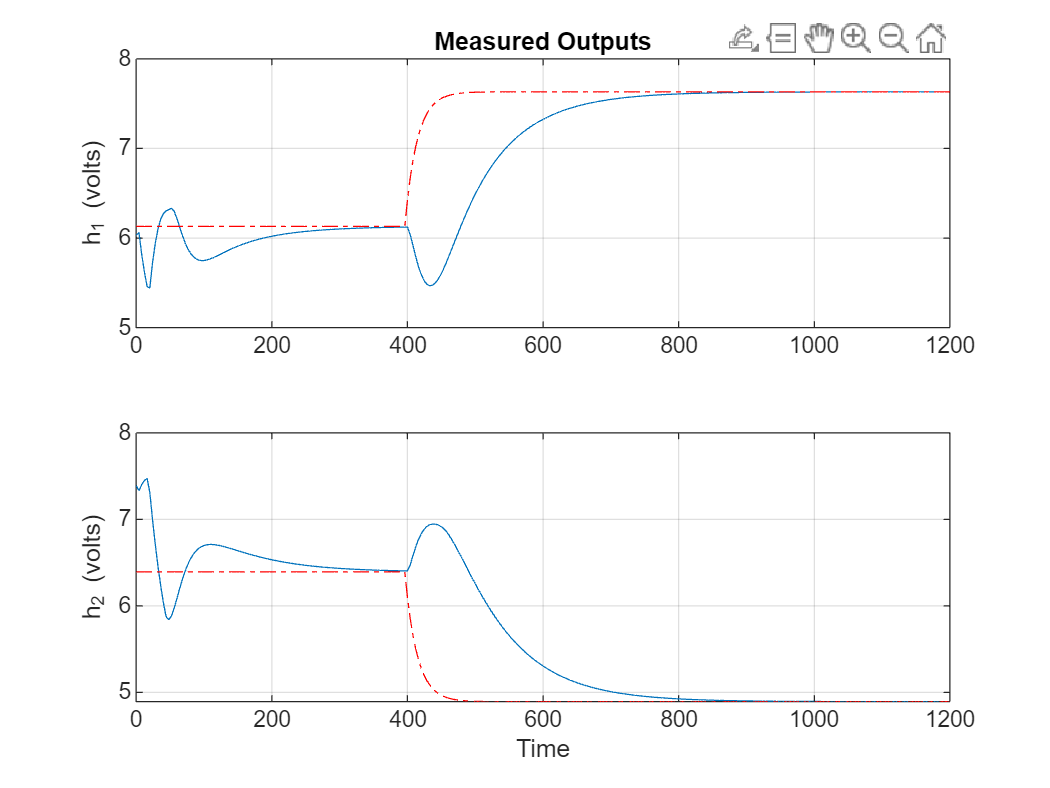

 % Specify input constraints  

Uk_Hi = [ 5 5 ]' ;
Uk_Lo = [ 0 0]' ;
 uk_H = Uk_Hi - QTank.Us ;
 uk_L = Uk_Lo - QTank.Us ; 
 
 % Setpoints 
 rk = zeros(n_op, Ns) ;    % Deviation setpoint
 Rk = zeros(n_op, Ns) ;    % Setpoint trajectory in original variables 

% Process Initial conditions
Xk(:,1) = QTank.Xs + 1 * [ -0.2 2 0.5 -0.5]' ;   % non-zero initial condition 

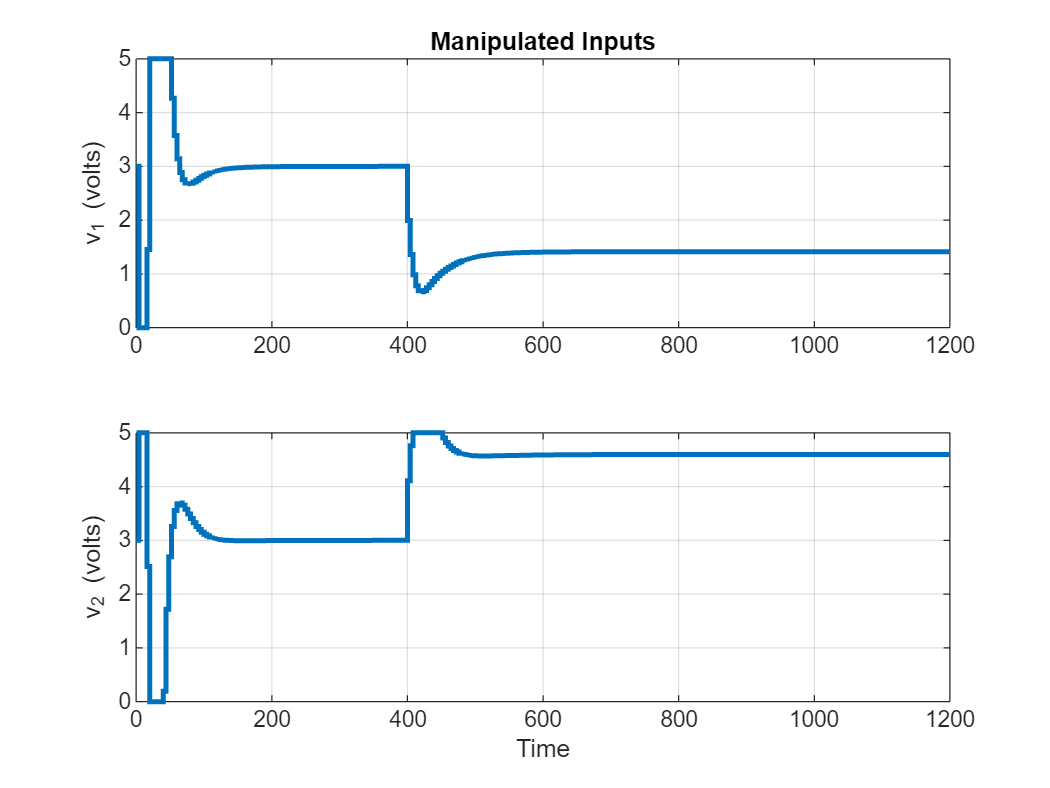

Yk(:,1) = QTank.C_mat * Xk(:,1)  ;   

% Perturbation Model: Initial conditions

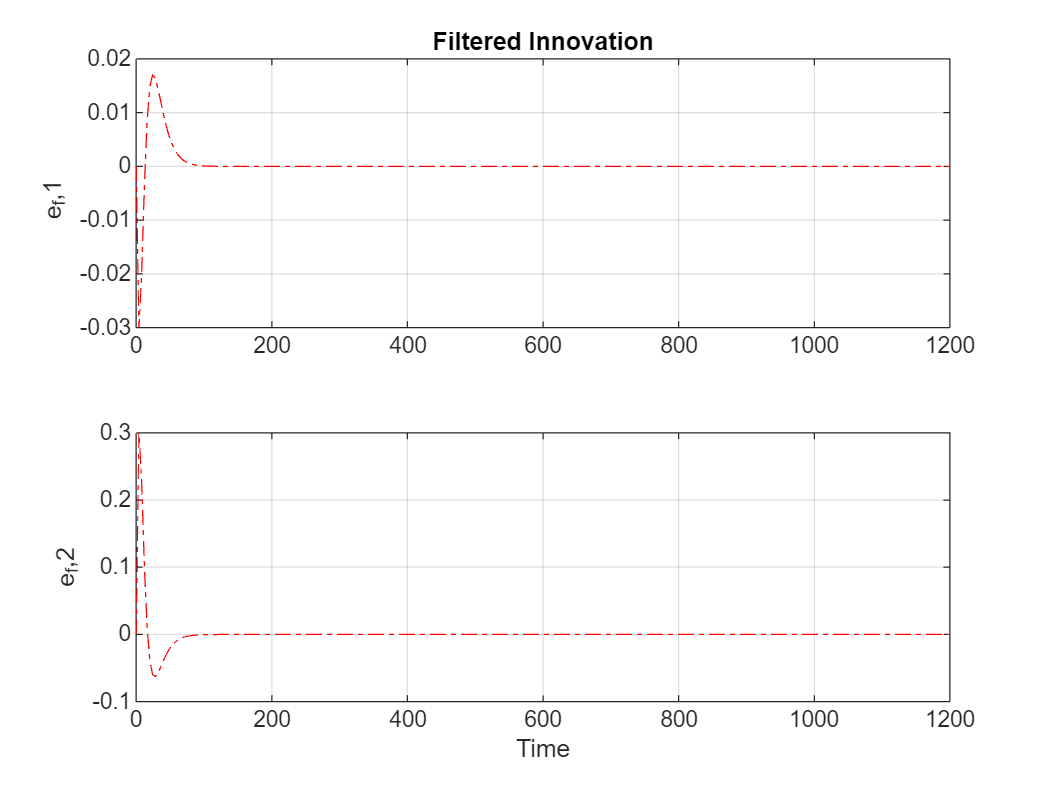

xk(:,1) = Xk(:,1) - QTank.Xs  ;   
yk(:,1) = Yk(:,1) - QTank.Ys   ;     
est_err(:,1) = xkpred(:,1) - xk(:,1);


% Dynamic simulation of Quadruple Tank system under open loop onditions
kT = zeros(1, Ns) ;  % Array to record time

There are two types of control objectives **(0) Disturbance Rejection, (1) Set Point Tracking**. Set the following variable named Servo Control to 0 for regulatory control and 1 for servo control. 

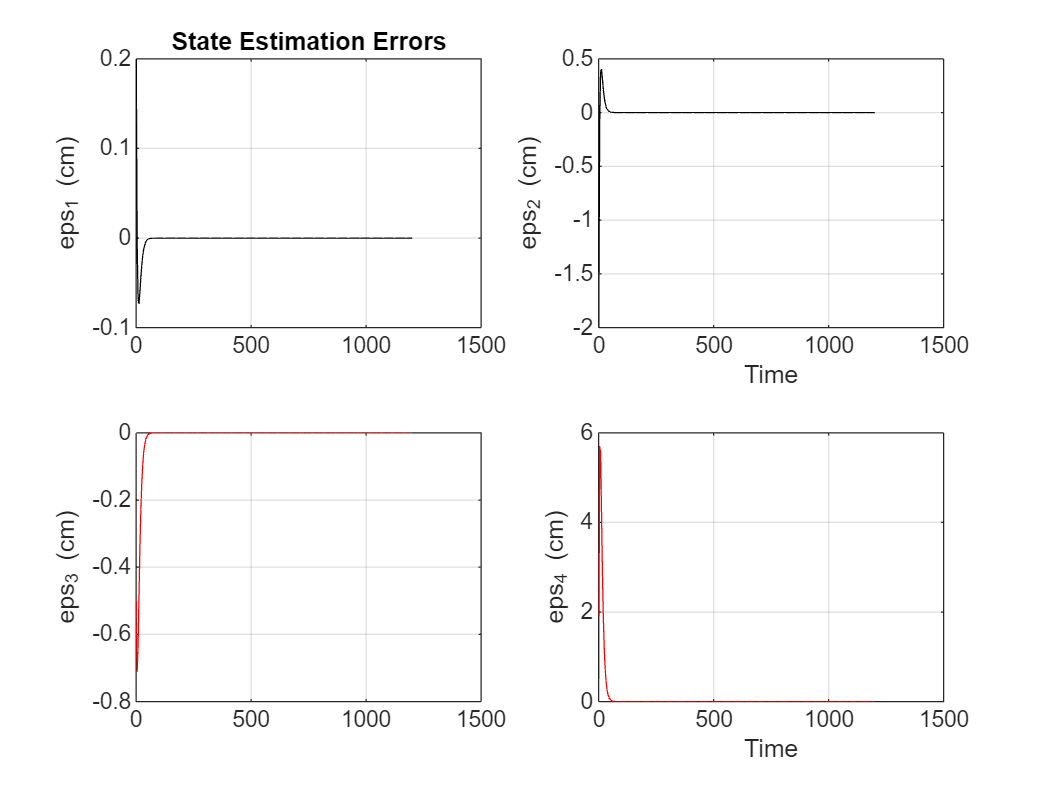

Servo_Problem=1; 


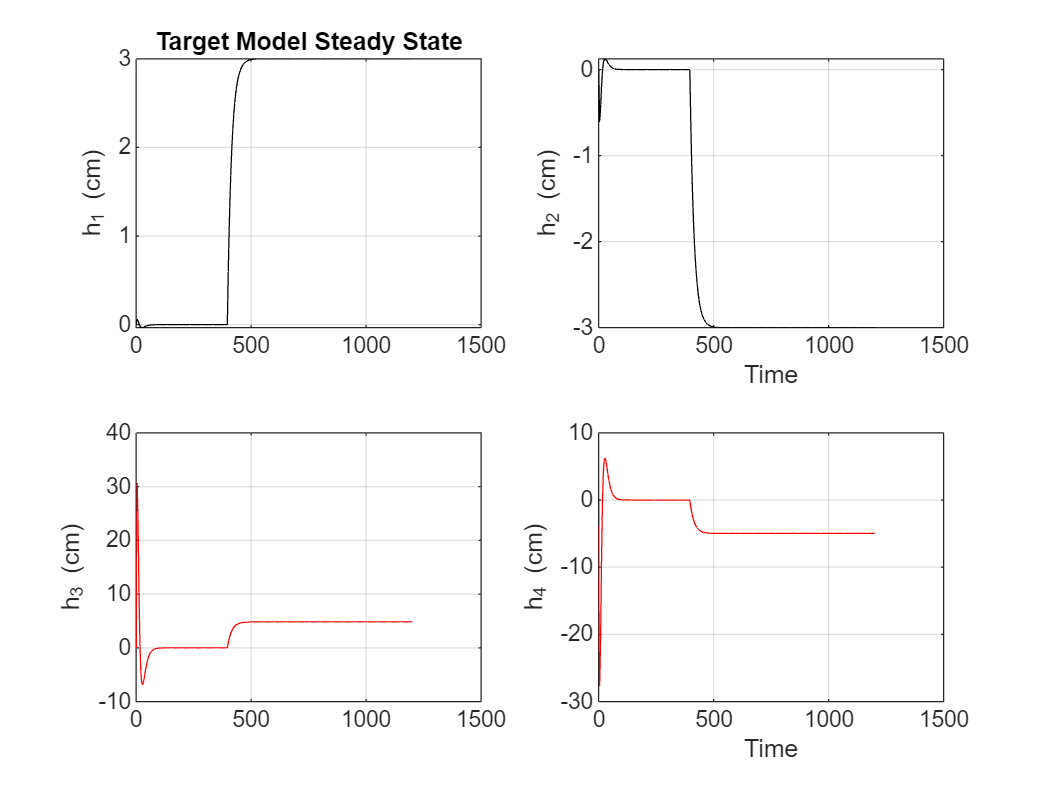

for k = 1 : Ns-1
                                % Print sampling instant on screen
    kT(k) = (k-1) * samp_T ;         % update time array 
    
    if ( Servo_Problem == 1 )

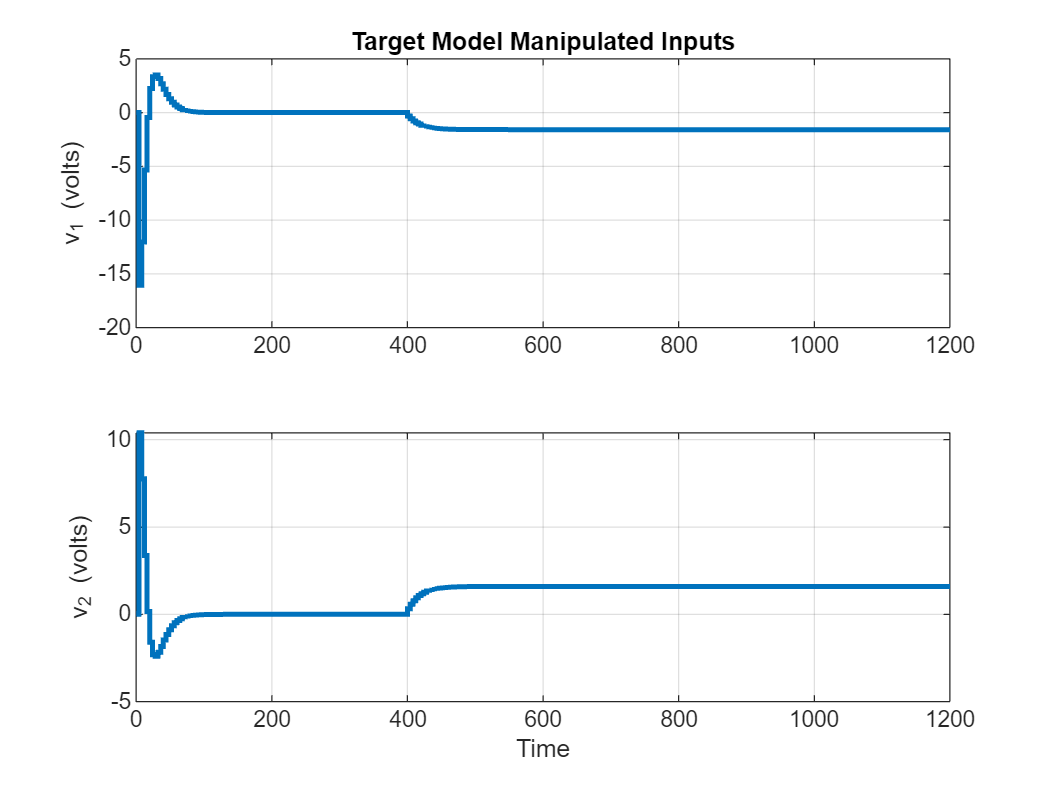

         if (k>= 100)  
             setpt = 1 * [1.5 -1.5]' ; 
         else 

             setpt =  [0 0]'  ; 
         end % Servo control
         dk = 0 ;
    else
         setpt = zeros(n_op,1) ;  
          if (k >= 100 ) 
              dk = -0.2 ; 
          else  
              dk = 0 ; 
          end  % Regulatory control
    end
    Rk(:,k) = QTank.Ys + rk(:,k) ;
     
    Dk(k) = QTank.Ds + dk ;      % Disturbance input  
    
    % Compute  inputs at sampling instant k using pole placement state feedback controller 
    
     % Generate filtered setpoint
     rk(:,k+1) = phy_r * rk(:,k) + (eye(n_op) - phy_r) * setpt ;

    % Compute target input and target states
    usk(:,k) = pinv(Ku_mat) * ( rk(:,k) - Ke_mat * ek_f(:,k) ) ;
    xsk(:,k) =  inv(eye(n_st) - QTank.phy) * ( QTank.gama_u * usk(:,k) +  Lp_mat * ek_f(:,k) ) ;

**Innovation Bias Controller Implementation:  **

Select  whether innovation bias  to be implemented or not

Set **compensate**  to 1,  if  MPM compensation is to be implemented, otherwise set it to 0. 

Initially let us use  the controller output without any compensation  for MPM. Control law in this case is 


$$u\left(k\right)=-G\hat{x\;} \left(k\right)$$


Observe  the  plant  outputs with  this controller. What  do we  observe? We see that there is a steady state error in the outputs.

Now change  the varaible **compensate to 1**.

 In this case the control law with innovation bias compensation is  

$u\left(k\right)=u_s \left(k\right)-G\left\lbrack \hat{x} \left(k\right)-x_s \left(k\right)\right\rbrack$.

Let us now observe the outputs. The  steady state error is eliminated. 


compensate=1;

   if  compensate==1
   uk(:,k) = usk(:,k)  - G_mat * (xkpred(:,k) - xsk(:,k))  ; 
   else
     uk(:,k) = - G_mat * (xkpred(:,k));% - xsk(:,k)  )  ;   
   end
      
     if ( uk(1,k) <= uk_L(1) )   % Inpose input constraints on uk(1) 
        uk(1,k) = uk_L(1) ;
    elseif ( uk(1,k) >= uk_H(1) )
            uk(1,k) = uk_H(1) ;
    end
    if ( uk(2,k) <= uk_L(2) ) % Inpose output constraints on uk(2)
        uk(2,k) = uk_L(2) ;
    elseif ( uk(2,k) >= uk_H(2) )
        uk(2,k) = uk_H(2) ;
    end
    Uk(:,k) =  uk(:,k) + QTank.Us   ;  % Manipulated input at instant k 
    
    %  Luenberger Predictor computations from instant (k) to (k+1) 
     yk(:,k )= Yk(:,k) - QTank.Ys ;
     ek(:,k) =  yk(:,k) - QTank.C_mat *  xkpred(:,k)  ;    % Compute Innovation 
     xkpred(:,k+1) = QTank.phy * xkpred(:,k) + QTank.gama_u * uk(:,k) + Lp_mat * ek(:,k)  ; 
    % Filtered innovation for innovation bias implementation
    ek_f(:,k+1) = phy_e * ek_f(:,k) + (eye(n_op) - phy_e) *  ek(:,k) ;
    
    % System Dynamics Simulation from sampling instant k to (k+1)
    if (plant_sim == 1 )
        % Plant Simulation using discete linear perturbation model
        xk(:,k+1) = QTank.phy * xk(:,k) + QTank.gama_u * uk(:,k) + QTank.gama_d * dk  ;
        yk(:,k+1) = QTank.C_mat * xk(:,k+1);
        Yk(:,k+1) =   yk(:,k+1) + QTank.Ys ;
    else
        % Equvalent to solving X(k+1) = F[ X(k), U(k), D(k) ]   and Y(k+1) = CX(k+1) +v(k+1)
        QTank.Uk = Uk(:,k)  ;    QTank.Dk = Dk(k) ;
        [T,Xt] = ode45( 'QTank_Dynamics', [ 0 samp_T ], Xk(:,k)) ;
        Xk(:,k+1) = Xt( end,: )' ;                           % State at instant (k+1)
        Yk(:,k+1) = QTank.C_mat * Xk(:,k+1);  % Measured output corrupted with noise
        % Create perturbation state for the sake of computing estimation errors
        xk(:,k+1) = Xk(:,k+1) - QTank.Xs   ;
    end
    
    est_err(:,k+1) = xkpred(:,k+1) - xk(:,k+1);   % State estimation error 
end

% specify input at the final instant : 
 kT(Ns) = Ns * samp_T ;      
 Uk(:,Ns)=   Uk(:,Ns-1) ;    % Input noise case
 Dk(Ns) = Dk(Ns-1) ;
 Rk(:,Ns) =  Rk(:,Ns-1) ;
  usk(:,Ns) = usk(:,Ns-1) ;
 xsk(:,Ns) = xsk(:,Ns-1)    ;
 

figure(1)
subplot(211), plot(kT, Yk(1,:), '-', kT, Rk(1,:), '-.r'), ylabel('h_1 (volts)'),   grid,title('Measured Outputs')
subplot(212), plot(kT, Yk(2,:), '-', kT, Rk(2,:), '-.r'), ylabel('h_2 (volts)'),  grid, xlabel('Time')
figure(2)
subplot(211), stairs(kT, Uk(1,:), '-', 'LineWidth', 2), ylabel('v_1 (volts)'),  grid, title('Manipulated Inputs')
subplot(212), stairs(kT, Uk(2,:), '-', 'LineWidth', 2), ylabel('v_2 (volts)'),  grid, xlabel('Time')
figure(3)
subplot(211), plot(kT, ek_f(1,:), '-.r'), ylabel('e_f,1 '), grid,  title('Filtered Innovation')
subplot(212), plot(kT, ek_f(2,:), '-.r'), ylabel('e_f,2'), grid,  xlabel('Time')
figure(4)
subplot(221), plot( kT, est_err(1,:), 'k'), ylabel('eps_1 (cm)'),  grid, title('State Estimation Errors')
subplot(222), plot(kT, est_err(2,:), 'k'), ylabel('eps_2 (cm)'),  grid, xlabel('Time')
subplot(223), plot(kT, est_err(3,:), 'r-'), ylabel('eps_3 (cm)'),  grid
subplot(224), plot(kT, est_err(4,:), 'r-'), ylabel('eps_4 (cm)'),  grid, xlabel('Time')
figure(5)
subplot(221), plot( kT, xsk(1,:), 'k'), ylabel('h_1 (cm)'),  grid, title('Target Model Steady State')
subplot(222), plot(kT, xsk(2,:), 'k'), ylabel('h_2 (cm)'),  grid, xlabel('Time')
subplot(223), plot(kT, xsk(3,:), 'r-'), ylabel('h_3 (cm)'), grid
subplot(224), plot(kT, xsk(4,:), 'r-'), ylabel('h_4 (cm)'),  grid, xlabel('Time')
figure(6)
subplot(211), stairs(kT, usk(1,:), '-', 'LineWidth', 2), ylabel('v_1 (volts)'),  grid, title('Target Model Manipulated Inputs')
subplot(212), stairs(kT, usk(2,:), '-', 'LineWidth', 2), ylabel('v_2 (volts)'),  grid, xlabel('Time')

## Conclusion:

Thus we have seen that the offset free state feedback cotroller can be achieved using **Innovation Bias compensation **technique. We have tested it for three different types of controllers. In the next chapter we will see implementation of [**State Augmentation approach**](matlab:open('./L06_OffsetFreeControl2.mlx'))